%{
Author: Milind Kumar V

This file contains code to simulate Jakes' model for Rayleigh fading. This
code is being written for the first programming assignment of the course
EE5141 at IIT Madras.
%}

% Remove all past results
clear;
% setting the random number generator
rng(1234);

% setting waveform sampling rate as defined in the problem
global sampRate
sampRate = 5000;


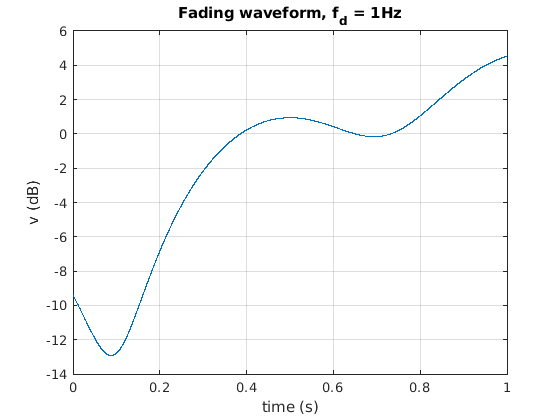

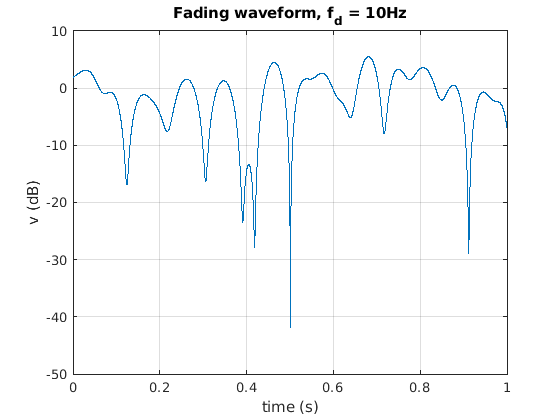

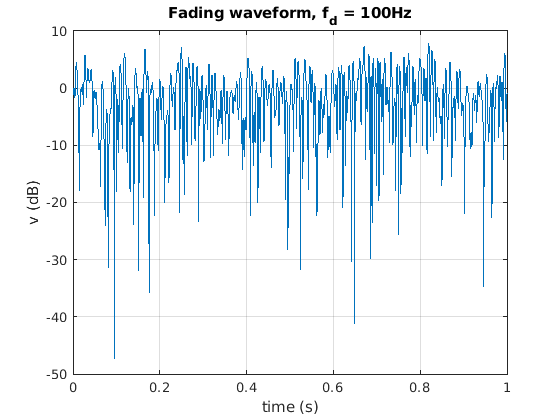

% Question 1a: Simulate Rayleigh fading using Jakes' model for different
% values of fd. Set M = 20 and duration = 1s.

fdArray = [1, 10, 100];
M = 20;
duration = 1;
time = linspace(0, duration, duration*sampRate);

for i = 1:length(fdArray)
    fdValue = fdArray(i);
    waveform = JakesModel(M, fdValue, duration);
    envelope = 20*log10(abs(waveform));
    % Plotting the envelope
    figure
    plot(time, envelope)
    grid on
    titleText = "Fading waveform, f_d = " + fdValue + "Hz"; 
    title(titleText)
    xlabel("time (s)")
    ylabel("v (dB)")
    
    
end

% Question 1b: Study the behavior of the level crossing rate by generating
% a rayleigh fading waveform multiple times.
M = 20; 
fd = 100;
duration = 5;
% Generating specified list of thresholds (in dB)
rhoList = -22:3:5;
% Expected value of LCR required, therefore multiple iterations
nIter = 100; 
% Level crossings over all iterations
nvMatrix = [];

for i = 1:nIter
    % Generate fading waveform for each trial
    waveform = JakesModel(M, fd, duration);
    envelope = abs(waveform);
    envelopeRMS = sqrt(mean(envelope.^2)); % redundant step
    envelope = envelope/envelopeRMS;
    envelopedB = 20*log10(envelope);
    envelopeMatrix = repmat(envelopedB, 1, length(rhoList));
    
    % Performing Level crossing detection
    levelDetect = envelopeMatrix > rhoList;
    levelCrossShift = [zeros(1, length(rhoList)); levelDetect(1:end-1,:)];
    levelCrossDetect = (levelDetect - levelCrossShift) > 0;
    nvIteration = sum(levelCrossDetect, 1);    
    nvMatrix = [nvMatrix; nvIteration];
end

nv = mean(nvMatrix, 1);
nvNormalized = nv/fd;


% converting rho to the linear scale
rholin = 10.^(rhoList/20);
nvIdeal = sqrt(2*pi)*rholin.*exp(-1*rholin.^2);


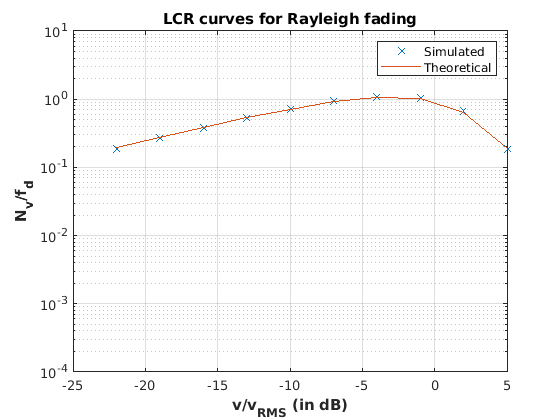

% plottinhg for figure 1b
figure
% waveform generated for 5s, therefore divide by 5
semilogy(rhoList, nvNormalized/5, "x" ) 
hold on
semilogy(rhoList, nvIdeal)
ylim([1e-4, 1e1 ])
title("LCR curves for Rayleigh fading")
xlabel("v/v_{RMS} (in dB)", "FontWeight","bold")
ylabel("N_v/f_d", "FontWeight","bold")
legend("Simulated", "Theoretical")
grid on
hold off

% Question 2c: Study the behaviour of the duration of fade for the rayleigh
% fading waveform.
M = 20;
fd = 10;
duration = 5;
% Generating specified list of thresholds (in dB)
rhoList = -22:3:5;
% Expected value of LCR required, therefore multiple iterations
nIter = 100; 
% Duration for each rho over all iterations
tauMatrix = [];

for i = 1:nIter
    % Generate fading waveform for each trial
    waveform = JakesModel(M, fd, duration);
    envelope = abs(waveform);
    envelopeRMS = sqrt(mean(envelope.^2)); % redundant step
    envelope = envelope/envelopeRMS;
    envelopedB = 20*log10(envelope);
    envelopeMatrix = repmat(envelopedB, 1, length(rhoList));
    
    % Determine the amount of time the signal spends under a given rho
    % value
    levelDetect = envelopeMatrix < rhoList;
    nSamplesLevels = sum(levelDetect, 1);
    tauIteration = (1/sampRate)*nSamplesLevels;
    tauMatrix = [tauMatrix; tauIteration];
    
end

tau = mean(tauMatrix, 1);
tauNormalized = tau*fd;

% Theoretical values for duration of fade 
rholin = 10.^(rhoList/20);
tauIdeal = (exp(rholin.^2) - 1)./(rholin*sqrt(2*pi));


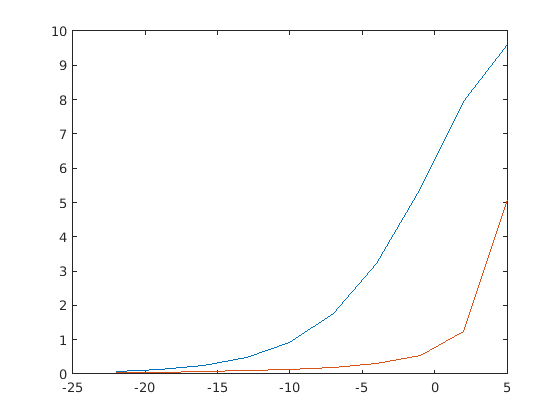

figure 
plot(rhoList, tauNormalized/5)
hold on
plot(rhoList, tauIdeal)

function zRealArray = zReal(M,fd,duration)
%{
zRealArray = zReal(M, fd, duration)

Inputs 
    M (int): M+1 oscillators are used in the system
    fd (float): maximum doppler frequency 
    duration (float): duration of the fading waveform in seconds
Outputs
    zRealArray (array): an array of the real parts of the (float) 
        fading waveform values of size number_of_samples x 1
%}
    N = 4*M + 2;
    global sampRate
    nSamples = duration*sampRate;
    timeArray = linspace(0, duration, nSamples)'; % time array needs to be a column vector
    
    % generating variables for vectorized code
    n = 1:M;
    betaArray = pi*n/(M + 1);
    fnArray = fd*cos(2*pi*n/N);
    phinArray = -pi + (pi - (-pi)).*rand(1,M);
    phi0 = -pi + (pi - (-pi)).*rand;
    fnMatrix = repmat(fnArray, nSamples, 1);
    
    % Generating zR
    scale = 2/(sqrt(N));
    cosTerm1 = cos(betaArray);
    cosTerm2 = cos(2*pi*(fnMatrix.*timeArray) + phinArray);
    term1Matrix = cosTerm1.*cosTerm2; 
    term1 = 2*sum(term1Matrix,2);
    term2 = sqrt(2)*cos(2*pi*fd*timeArray + phi0);
    
    zRealArray = scale*(term1 + term2);
        
end


%{
zImagArray = zImag(M, fd, duration)

Inputs 
    M (int): M+1 oscillators are used in the system
    fd (float): maximum doppler frequency 
    duration (float): duration of the fading waveform in seconds
Outputs
    zImagArray (array): an array of the imaginary parts of the (float) 
        fading waveform values of size number_of_samples x 1
%}

function zImagArray = zImag(M,fd,duration)
    N = 4*M + 2;
    global sampRate
    nSamples = duration*sampRate;
    timeArray = linspace(0, duration, nSamples)'; % time array needs to be a column vector
    
    % generating variables for vectorized code
    n = 1:M;
    betaArray = pi*n/(M + 1);
    fnArray = fd*cos(2*pi*n/N);
    phinArray = -pi + (pi - (-pi)).*rand(1,M);
    fnMatrix = repmat(fnArray, nSamples, 1);
    
    % Generating zR
    scale = 2/(sqrt(N));
    sinTerm1 = sin(betaArray);
    cosTerm2 = cos(2*pi*(fnMatrix.*timeArray) + phinArray);
    term1Matrix = sinTerm1.*cosTerm2; 
    term1 = 2*sum(term1Matrix,2);
    
    zImagArray = scale*(term1);

end

%{
zSequence = JakesModel(M, fd, duration)

Inputs 
    M (int): M+1 oscillators are used in the system
    fd (float): maximum doppler frequency 
    duration (float): duration of the fading waveform in seconds
Outputs
    zSequence (array): an array of the of the (float) 
        fading waveform values of size number_of_samples x 1
%}

function zSequence = JakesModel(M, fd, duration)
    zSeq = zReal(M,fd,duration) + 1j*(zImag(M, fd, duration));
    zSeqPower = mean(abs(zSeq).^2); % FIXME: square or not?
    scale = 1/sqrt(zSeqPower); % FIXME: remove sqrt?
    zSequence = scale*zSeq;
end